Szereg Taylora pozwala obliczyć wartość funkcji w punkcie *x* w pobliżu punktu *x0*, w którym wartość tej funkcji jest znana (o ile znane są też jej wszystkie pochodne w tym punkcie):

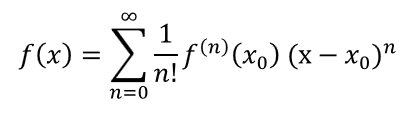

W praktyce inżynierskiej często wystarczające okazuje się uwzględnienie dwóch (lub ew. trzech) pierwszych wyrazów tego szeregu:

 lub 

Obrazuje to poniższy przykład, który pozwala wyznaczyć dokładność takiego przybliżenia w zależności od odległości punktu *x* od punktu *x0* (odległość tę oznaczono zmienną *h*). Wybierz funkcję, punkt, który będzie przyjmowany za znany oraz liczbę elementów szeregu, które zostaną uwzględnione w obliczeniach, a następnie uruchom skrypt i obserwuj wyniki. Wykonaj następujące zadania:

- Znajdź takie dane wejściowe, dla których błąd przybliżenia będzie zerowy lub będzie liczbą rzędu błędu reprezentacji zmiennej typu double,

- Znajdź dane wejściowe i argument, dla którego błąd względny asymptotycznie dąży do nieskończoności. Czy wiesz dlaczego?

clear all;
close all;
%wybór funkcji, z której będzie obliczana całka
syms f(x)
f(x)=sin(x)

$$f(x) = \sin\left(x\right)$$

%Rozwiń wokół domyślnego punktu:
deafX0=true

deafX0 = logical
   1



if deafX0==true
    x0=1
else
    x0=input("Podaj x0, wokół którego funkcja zostanie rozwinięta w szereg:")
end

x0 = 1


%Wybierz liczbę elementów szeregu dla przybliżenia
N=2

N = 2


 

disp('Wartosc funkcji f(x0) = ')

Wartosc funkcji f(x0) = 


double(f(x0))

ans = 0.8415

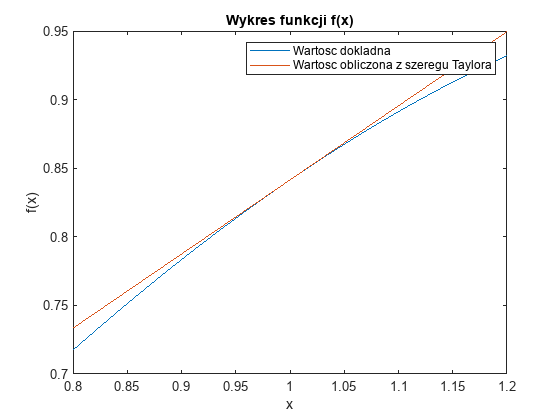

%WYZNACZANIE POCHODNYCH%%%%%%%%%%%
if strcmp(string(char(f(x))),"sin(x)")
        fprim=@(x) cos(x);
        fbis=@(x) -sin(x);
        ftert=@(x) -cos(x);
end
if strcmp(string(char(f(x))),"x^3 - 2*x^2 - 5*x - 3")
        fprim=@(x) 3*x^2-4*x-5;
        fbis=@(x) 6*x-4;
        ftert=@(x) 6;
end
if strcmp(string(char(f(x))),"3*x^4 - 2*x + x^6")
        fprim=@(x) 6*x^5+12*x^3-2;
        fbis=@(x) 30*x^4+36*x^2;
        ftert=@(x) 120*x^3+72*x;
end
if strcmp(string(char(f(x))),"exp(x)")
        fprim=@(x) exp(x);
        fbis=@(x) exp(x);
        ftert=@(x) exp(x);
end    
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

h=linspace(-0.2,0.2,2001);
fx_dokl=double(f(x0+h));
if N==2
    fx_T=double(f(x0))+h.*fprim(x0);
elseif N==3
    fx_T=double(f(x0))+h.*fprim(x0)+1/2.*h.^2*fbis(x0);
elseif N==4
    fx_T=double(f(x0))+h.*fprim(x0)+1/2.*h.^2*fbis(x0)+1/6.*h.^3*ftert(x0);
end
err_bw=abs(fx_dokl-fx_T);
err_wzgl=err_bw./abs(fx_dokl);

figure()
plot(x0+h,fx_dokl, x0+h, fx_T)
title 'Wykres funkcji f(x)'
xlabel 'x'
ylabel 'f(x)'
legend('Wartosc dokladna', 'Wartosc obliczona z szeregu Taylora')

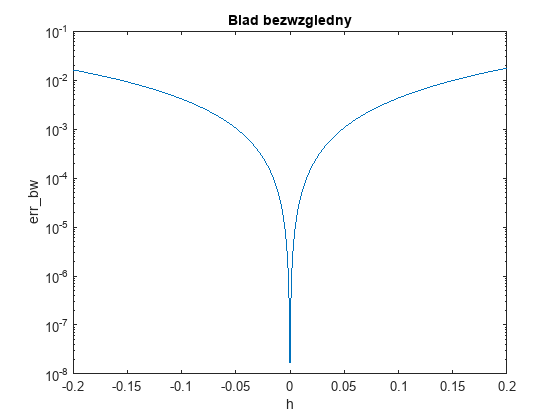


figure()
semilogy(h,err_bw)
title 'Blad bezwzgledny'
xlabel 'h'
ylabel 'err\_bw'

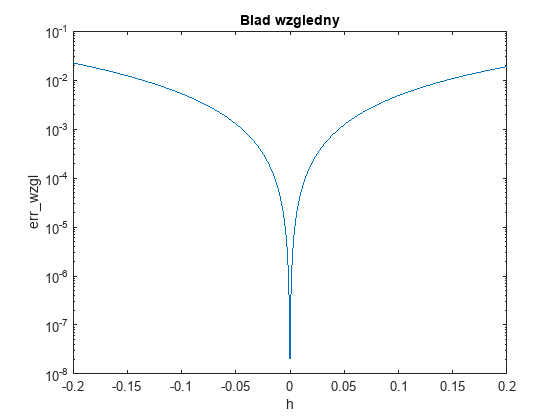


figure()
semilogy(h,err_wzgl)
title 'Blad wzgledny'
xlabel 'h'
ylabel 'err\_wzgl'

Warto wiedzieć, że w Matlabie istnieje wbudowana funkcja *taylor*, która przybliża funkcje (wbudowane w Matlabie takie jak: *exp, log, sin, cos* itp.) rozwinięciem w szereg Taylora zadanego rzędu (uwzględniając odpowiednią liczbę czynników rozwinięcia).